# Assignment 9b - The Discrete-Time Fourier Transform (Matlab)

## 5.1 Computing Samples of the DTFT

This exercise will examine the computation of the discrete-time Fourier transform (DTFT)

in MATLAB. A fundamental difference between the DTFT and the CTFT is that the

DTFT is periodic in frequency. Mathematically, this can be shown by examining the DTFT

equation, 

    
$$X(e^{j(w+2\pi)})=\sum_{n=-\infty}^\infty\ x[n]e^{-j(w+2\pi)n}= \sum_{n=-\infty}^\infty\ x[n]e^{-jwn}(1)^n\\
= X(e^{jw})$$


The function **fft **implements Eq. (5.3) in a computationally efficient manner. If **x** is a

vector containing *x[n]*  for $0\le n\le M-1$and $N\ge M$, then **X=fft (x , N)** computes *N* evenly

spaced samples of the DTFT of **x** and stores these samples in the vector **X**. If *N < M*, then

the MATLAB function **fft** truncates **x** to its first *N* samples before computing the DTFT,

thus yielding incorrect values for the samples of the DTFT. You will see how to compute

fewer than *M* frequency samples in one of the following problems.

    The values of **X(k)** for* k > N/2* are also samples of $X(e^{jw})$ on the interval $-\pi\le w < 0$,

due to the periodicity of the DTFT. If you want to reorder the DTFT samples returned

by **fft **to correspond to the interval $-\pi\le w_k < \pi$ the MATLAB function **fftshift **was

written specifically to swap the second half of the vector **X** with the first half.

### Basic Problems

(a). Calculate an alytically the DTFT of the rectangular pulse defined by $x[n]=u[n]-u[n-11]$.  Also create the vector **x** containing the nonzero samples of *x[n]*.

**5.1a Analysis:**

$x_1[n]=u[n+5]-u[n-5]$ and $x[n]=x_1[n-5]$

From time-shifting property, we have: 

                
$$X(e^{j\omega})=e^{-5j\omega}X_1(e^{j\omega})$$


Using Table5.2, we can see that 

    
$$x_1  = \left\{
        \begin{array}{ll}

      0, & |n|>N_1 \\


     1,  &  |n|\le N_1   \\


 \end{array}
    \right.$$


where $N_1=5$

Therefore,

        
$$X_1(e^{j\omega})=\frac{sin( \omega(N_1 +1/2)     )   }{ sin( \omega/2)   } = \frac{sin( \omega(5 +1/2)     )   }{ sin( \omega/2)   } \\


X_1(e^{j\omega})= \frac{sin( \omega(5 +1/2)     )   }{ sin( \omega/2)   } e^{-5j\omega}\\$$


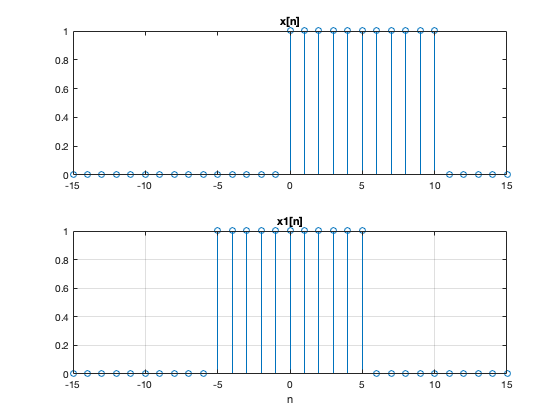

%5.1a Code
clf;
n=[-15:15];
x=(n>=0 & n<=10).*1 + (n<0 & n>11).*0;
subplot(2,1,1); stem(n,x);  title('x[n]');
x1=(n>=-5 & n<=5).*1 + (n<-5 & n>5).*0;
subplot(2,1,2); stem(n,x1);  title('x1[n]'); xlabel('n'); grid;

(b). Create a vector of *N = 100* frequencies containing the frequency samples** w=2*pi*k/N**

for** k= [0: N-1]**. Plot $|X(e^{jw})|$ over this range, using the formula you calculated in

Part (a). Also plot the phase $\angle X(e^{jw})$. You may find the following function helpful

This function is provided in the Computer Explorations Toolbox, or you can create a

new** M-file **for it.

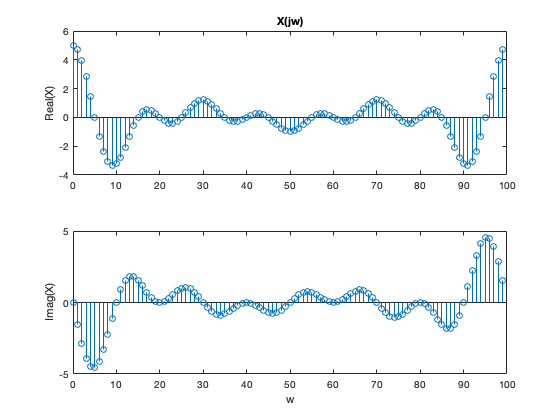

%5.1b Code
clf;
N=100;
k=[0:N-1];
w=2*pi*k/N;

X1=dtftsinc(5,w);
X=X1.*exp(-5j*w);
figure;
subplot(2,1,1);    stem(k,real(X)); title('X(jw)'); ylabel('Real(X)');
subplot(2,1,2);    stem(k,imag(X)); xlabel('w');    ylabel('Imag(X)');

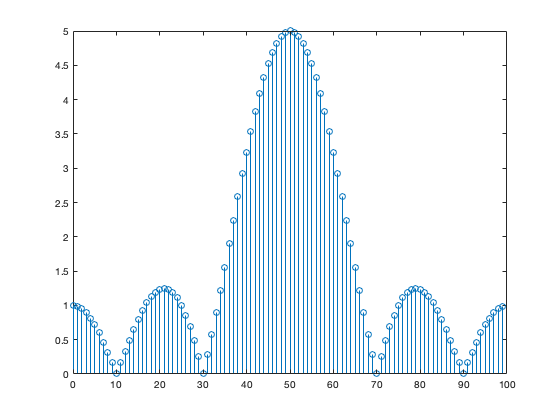


figure;
stem(k,abs(fftshift(X)));

(c). Rearrange the frequency samples to correspond to the principle period of the DTFT,

$-\pi\le w <\pi$. To do this, use** w=w-pi**. Use the function **fft **to calculate* N=100* samples

of the DTFT of *x[n]* and store your result in the vector **X**. Plot the magnitude and

phase of **X** versus **w**. Don't forget to use **fftshift** to rearrange the DTFT samples

in **X** to match the frequencies in **w**. How does this plot compare to your results from

Part (b)?

**5.1c Analysis:**

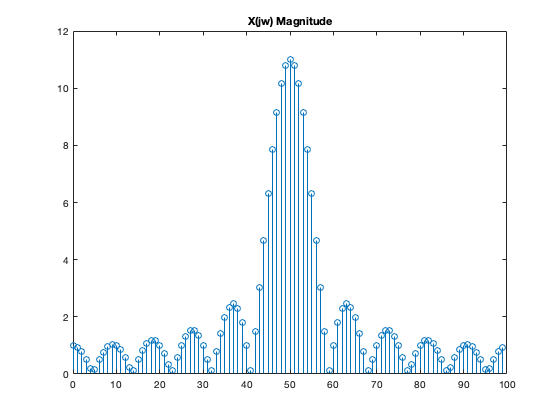

%5.1c Code

clf;
w=w-pi;
N=100;
X=fftshift(fft(x,N));
figure;
stem(k,abs(X)); title("X(jw) Magnitude");

(d). Use the time-shift property of the DTFT to calculate analytically the DTFT of the

signal* x[n + 5]*, i.e., the centered pulse. You should get an answer that is purely

real. Again, using the time-shift property of the DTFT, determine the value of the

parameter a so that **Xr=exp (j*w*a) . *X** corresponds to the DTFT of* x[n + 5].* Plot **Xr**

versus **w**. You may have to use the function real to remove any small imaginary parts

of your result. Also use the function **dtftsinc** along with your analytic expression

for the DTFT of *x[n + 5]* to verify your answer.

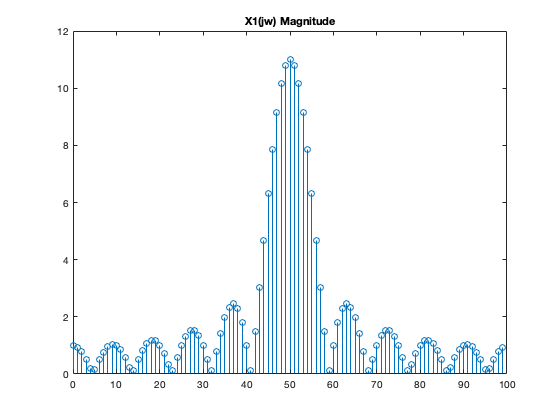

%5.1d Code
X1=X.*exp(5j*w);
figure;
stem(k,abs(X1)); title("X1(jw) Magnitude");

(e). Use **fft** to compute the DTFT of the signal $z[n]=(5-|n|)(u[n+5]-u[n-5])$. Plot

the DTFT of *z[n*] versus **w**. Hint: The DTFT of z[n] should be a purely real function

of w.

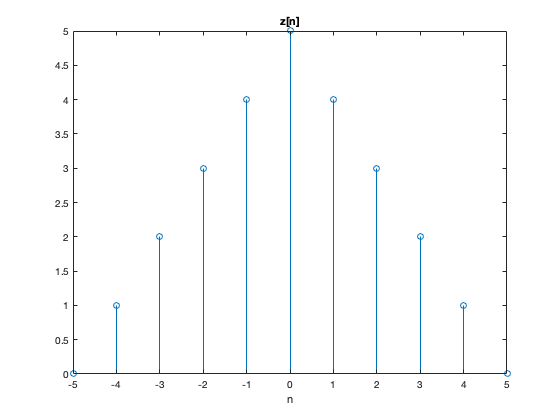

%5.1e Code
nz=[-5:5];
z=[0 1 2 3 4 5 4 3 2 1 0];
stem(nz,z);  title('z[n]');    xlabel('n');

**Analysis**

The plot represent $z[n]$ is a real and even signal, therefore it's FT should be purely real function of w.

## 5.2 Telephone Touch-Tone

This exercise will teach you how the touch-tone system on the telephone uses signals of

different frequencies to indicate which key has been pushed. The DTFT of a sampled

telephone signal can be used to identify these frequencies. The sound you hear when you

push a key is the sum of two sinusoids. The higher frequency sinusoid indicates the column

of the key on the touch-pad and the lower frequency sinusoid indicates the row of the key

on the touch-pad. Figure 5.1 shows the layout of a telephone keypad and the two DTFT

frequencies corresponding to each digit, assuming the continuous-time waveform is sampled

at 8192 kHz. The figure also contains a table listing each digit and the DTFT frequencies

for that digit. For example, the digit 5 is represented by the signal

    
$$d_5[n]=sin(0.5906n)+sin(1/0247n)$$


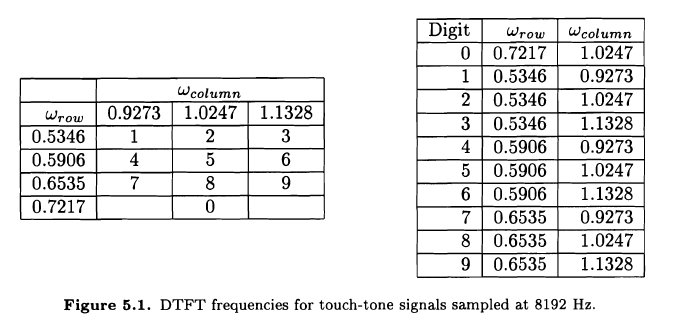

### Basic Problems

In these problems, you will create the appropriate touch-tone for each digit, and examine

the DTFT to make sure the signals have the correct frequencies. You will also define a

vector containing the touch-tones for your phone number.

(a). Create row vectors **d0** through **d9** to represent all 10 digits for the interval $0\le n \le 999$.

Listen to each signal using sound. For example, **sound(d2,8192)** should sound like

the tone you hear when you push a '2' on the telephone.

%5.2a Code
n=[0:999];
fs=8192;
d0= sin(0.7217.*n)+ sin(1.0247.*n);
d1= sin(0.5346.*n)+ sin(0.9273.*n);
d2= sin(0.5346.*n)+ sin(1.0347.*n);
d3= sin(0.5346.*n)+ sin(1.1328.*n);
d4= sin(0.5906.*n)+ sin(0.9273.*n);
d5= sin(0.5906.*n)+ sin(1.0247.*n);
d6= sin(0.5906.*n)+ sin(1.1328.*n);
d7= sin(0.6535.*n)+ sin(0.9273.*n);
d8= sin(0.6535.*n)+ sin(1.0247.*n);
d9= sin(0.6535.*n)+ sin(1.1328.*n);
D=[d0, d1, d2, d3, d4, d5, d6, d7, d8, d9];
for i = 0:9
    dailtone=D((i*1000+1):(i+1)*999);
    sound(dailtone,8192);
    pause(0.1);
end

(b). The function **fft** can be used to compute **N** samples of the DTFT of a finite-length

signal at frequencies $w_k=2\pi k/N$. For example,** X = fft (x, 2048)** computes 2048

evenly spaced samples of$X(e^{jw})$ at $w_k=2\pi k/2048$ for $0\le k \le 2047$. Use **fft** to

compute samples of $D_2(e^{jw})$ and$D_9(e^{jw})$at $w_k=2\pi k/2048$. Define **omega** to be a

vector containing $w_k$, for $0\le k \le 2047$. Plot the magnitudes of the DTFTs for these

signals, and confirm that the peaks fall at the frequencies specified in Figure 5.1. You

will find it easier to see which frequencies are present if you use **axis** to restrict the

*w*-axis to the region $0.5\le w\le 1.25$ while keeping the full vertical range. Generate

appropriately labeled plots of the DTFT magnitudes for these two digits.

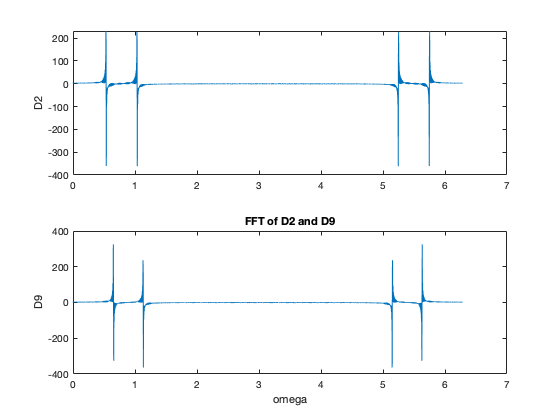

%5.2b Code
N=2048;
k=0:2047;
w=2*pi*k/N;
D2=fft(d2,N);
D9=fft(d9,N);
figure;
subplot(2,1,1); plot(w,real(D2)); ylabel("D2");
subplot(2,1,2); plot(w,real(D9)); ylabel("D9");
title('FFT of D2 and D9');  xlabel("omega")

(c). Define **space** to be a row vector with 100 samples of silence using zeros. Define

phone to be your phone number by appending the appropriate signals and **space**. For

instance, if your phone number was 555-7319, you would type

`>> phone = [d5 space d5 space d5 space d7 space d3 space d1 space d9] ;`

Note that in order to append the signals this way, all of the digits you defined in

Part (a) and **space** must be row vectors. Play your phone number using **sound** and

verify that it sounds the same as when you dial it on a touch-tone phone.

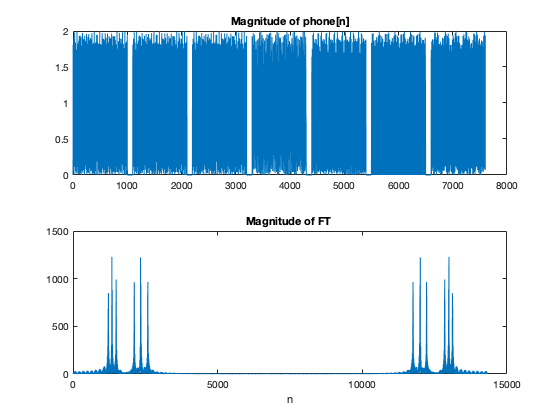

%5.2c Code
space=zeros(1,100);
phone = [d5 space d5 space d5 space d7 space d3 space d1 space d9] ;
sound(phone,fs)
subplot(2,1,1); plot(abs(phone));  title('Magnitude of phone[n]');
P=fft(phone,N*7);
subplot(2,1,2); plot(abs(P));  title('Magnitude of FT ');  xlabel('Omega');
xlabel('n');

## 5.3 Discrete-Time All-Pass Systems

This exercise explores the effect of all-pass systems on discrete-time signals. All-pass systems

are defined to have a frequency response with magnitude equal to one, i.e., $|H(e^{jw})|=1$.

The magnitude of the DTFT of the output signal of an all-pass system is identical to the

magnitude of the DTFT of the input signal. However, as will be demonstrated in this

exercise, the phase of the frequency response can lead to significant distortion in the output

of the system.

    You will work with two different discrete-time all-pass systems in this exercise. Both of

these systems are causal LTI systems. Their inputs and outputs satisfy the following linear,

constant-coefficient difference equations:

    System 1: $y[n]=x[n-3]$,

    System 2: $y[n]-(3/4)y[n-1]=-(3/4)x[n]+x[n-1]$.

### Basic Probelems: 

(a). Define coefficient vectors **a1** and **b1** for System 1 and use **freqz **to generate appropriately

labeled plots of the magnitude and phase of the frequency response $H_1(e^{jw})$ of

this system. If you are unfamiliar with **freqz**, you may wish to review Tutorial 3.2.

Do your plots confirm that the system is an all-pass system?

**5.3a Analysis: **	

For System 1: $a_1 = 1$, and $b_1 = [0 0 0 3]$. 				

The computation and plot show that the frequency resonse $H_1(e^{j\omega})$ has magnitude of one across the interval, $0\le  \omega < 2\pi$. Therefore System 1 is an all-pass system. 

%5.3a Code
a1=1;
b1=[0 0 0 1];
% number of sample points
N=50;
[H1 omega]=freqz(b1,a1,N,"whole");
k=[0:N-1];
w=(2*pi/N).*k;
subplot(2,1,1); stem(w,abs(H1));
title('Magnitude of H1');
subplot(2,1,2); stem(w,angle(H1));
title('Phase of H1'); xlabel('0 <= n <= 2pi');

(b). Define coefficient vectors **a2** and **b2** for System 2 and generate plots of the magnitude

and phase of the frequency response of this system. Again, your plots should show

that $|H_2(e^{jw})|=1$ for all *w*. Is the phase of $H_2(e^{jw})$ the same as the phase of $H_1(e^{jw})$?

When the inputs to both systems are the same, would you expect the outputs to be

the same?

**5.3b Analysis**

For System 2: $ a_2 = [1 -3/4]$,  and $b_2 = [-3/4 1].$ 

%5.3b Code

a2=[1 -3/4];
b2=[-3/4 1];
% number of sample points
N=50;
[H2 omega]=freqz(b2,a2,N,"whole");
k=[0:N-1];
w=(2*pi/N).*k;
subplot(2,1,1); stem(w,abs(H2));
title('Magnitude of H2');
subplot(2,1,2); stem(w,angle(H2));
title('Phase of H2'); xlabel('0 <= n <= 2pi');

## 5.4 Frequency Sampling: DTFT-Based Filter Design

The frequency response of any stable LTI filter is given by the DTFT of its impulse response.

Because MATLAB can be used to compute samples of the DTFT of finite-length signals,

as shown in Exercise 5.1, MATLAB can also be used to compute samples of the frequency

response of finite-length impulse response (FIR) filters. In this exercise, you will use the

DTFT to design an FIR filter from samples of the desired frequency response. Since this

method of filter design only specifies the frequency response at a set of frequency samples,

it is often called "frequency sampling".

    The frequency response of an FIR filter whose impulse response h[n] is nonzero only on

the interval $0\le n \le N-1$ is given by

    $H(e^{jw})=\sum_{n=1}^{N-1}\ h[n]e^{-jwn}$ .                     (5.9)

Exercise 5.1 demonstrates how to use the function **fft** to compute *N* equally spaced samples

of the DTFT. In this set of problems, you will specify the values of the DTFT at these *N*

frequency values, and then will use the operator **\** to solve the set of linear equations

that result. The FIR filter will be an approximation to the ideal lowpass filter with cutoff

frequency $w_c=\pi/2$,

    $H_{id}(e^{jw})=\begin{cases}
1,\ |w|<\pi/2,\\
0,\ \pi/2\le |w|\le \pi 
\end{cases}$ .               (5.10)

### Basic Probelems

(a). Draw the desired frequency response magnitude over the range $0\le w\le 2\pi$. Remember

that the DTFT is periodic with period $2\pi$.

%5.4a Code
n=0:0.3:2*pi;
H_id=(n>=0 & n<pi/2).*1+(n>=pi/2).*0;
figure;

stem(n,H_id);  grid; title('Magnitude - System response of H_{id}');  xlabel('0 <= w < 2pi');

(b). Construct the vector corresponding to the* N *= 9 equally spaced frequencies from 0 to

$2\pi$, **w=2*pi*k/N**, for **N=9** and **k= [0:N-1]** . Store in a vector Hm the desired frequency

response magnitudes $|H_{id}(e^{jw})|$ that correspond to the frequencies in the vector **w**.

Plot the desired frequency response magnitude versus w, using **plot (w,Hm)**. Does

your plot look like a lowpass filter?

**5.4b Analysis:**

%5.4b Code
clf;
N=9;
k=0:N-1;
w=2*pi*k/N;
Hm=(w>=0 & w<pi/2).*1 + (w>=pi/2).*0;
figure;
stem(w,Hm); grid; title('Magnitue - system response of H_m');  xlabel('0 <= w < 2pi');

(c). Now that the frequency response magnitude has been specified, you need to specify

the phase. The frequency response $H(e^{jw})$ could be made purely real if *h[n]* were

symmetric about *n = 0*. In this case, $H(e^{jw})$ would have zero phase. However, as

assumed by Eq. (5.9), the impulse response you are to compute must be causal, and

thus cannot be symmetric about n = 0. What is the phase of the causal filter *h[n]*,

which is related to the zero-phase filter by a delay of *(N - 1)/2* samples? Store in the

vector **Hp** the values of this phase at the frequency samples contained in **w**. Hint: The

phase should be of the form aw for frequency samples $|w|\le \pi$. Use the periodicity of

$H(e^{jw})$ to determine the phase samples in **Hp **for $w > \pi$.

**5.4c Analysis: **

%5.4c Code
N=9;
k=0:N-1;
w=2*pi*k/N;
Hm=(w>=0 & w<pi/2).*1 + (w>=pi/2).*0;
% get the phase of Hm(jw)
H1 = angle(Hm);
stem(w,H1);  title('zero phase filter Hm'); xlabel('0 <= w < 2*pi');

Hc=(w>=0 & w<pi*3/4).*0 + (w>=pi*3/4 & w<pi*7/4).*1;
stem(w,Hc); title(' Magnitude of Casual filer'); xlabel('0 <= w < 2*pi');

Hp = angle(Hc);
stem(w,Hp);  title('phase of causal filter Hh'); xlabel('0 <= w < 2*pi');

function X=dtftsinc(M,w)
den=sin(w/2);
num=sin(M*w/2);
X=zeros(size(w));
X(den~=0)=num(den~=0)./den(den~=0);
X(den==0)=M;
end